# **RT-QIBC  analysis**

**Variables:**

YFP1 = mean Cdt1 IF intensity within nucleus

FarRed1 = mean Cdt1 IF intensity within nucleus

POI_time(:,3) = time since CRL4Cdt2 activation

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';

impath = fullfile(dataDir,'C223_Images',filesep);
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    %     'DMSO',2,3,1:9,[0 0 0]; %1
    'DMSO',2:7,2,1:9,[0 0 0]; %1
    'DOX 50',2:7,3:6,1:9,[0 0 0]; %1
    'DOX 1',2:7,7:11,1:9,[0 0 0]; %1
    };


load([dataDir filesep 'C223_data.mat'],'S');
%S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};


**Set thresholds**

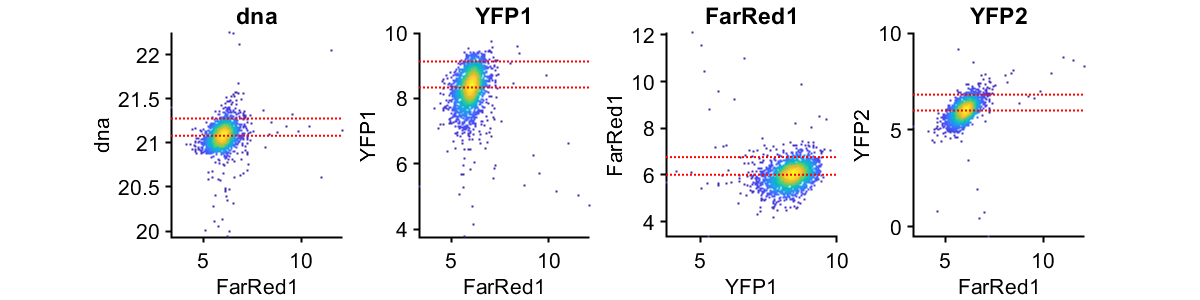

%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP1','FarRed1','YFP2'};
plotting = {'FarRed1','FarRed1','YFP1','FarRed1'};
prctiles = {[50 95], [50 95],[50 95],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 &...
        isnan(S(cond).POI(:,3));
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

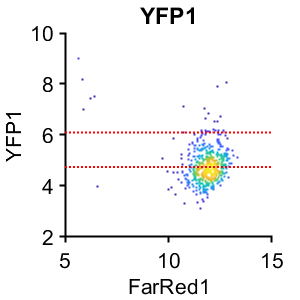


gates = {'YFP1'};
plotting = {'FarRed1'};
prctiles = {[50 95]};
figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 3 & S(cond).POI_time(:,3) > 1;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

f = figure('units','inches','pos',[0 0 4 4]);
data = {};
cond = 1;
inds = S(cond).YFP1 > 2^2 & S(cond).YFP1 < 2^13 & S(cond).POI_time(:,1) < 3 & S(cond).POI_time(:,1) > 1 & isnan(S(cond).POI_time(:,3));
data =[ data real(log2(S(cond).YFP1(inds)))];

conds=[1 2];
for i=1:length(conds)
    condition = conds(i);
    inds = S(condition).POI_time(:,3) < 1 & S(condition).YFP1 > 2^2 & S(condition).YFP1 < 2^13;
    data = [data real(log2(S(condition).YFP1(inds)))];
end

trunc_thresh = 8;
% endo_thresh = prctile(data{1}(data{1} > trunc_thresh),75)
[p, xi] = ksdensity(data{1});
trunc_xi = xi(xi > trunc_thresh);
trunc_p = p(xi > trunc_thresh);
[~,i] = max(trunc_p);
endo_max = trunc_xi(i);
trun_data = data{1}(data{1} > endo_max);
endo_thresh = prctile(trun_data,(75 - 50)*2);
nhist(data,'samebins','pdf','noerror','separate','minx',2,'maxx',13,'LineWidth',1.5);

data

data = 1×3 cell array
    {3431×1 double}    {382×1 double}    {1447×1 double}


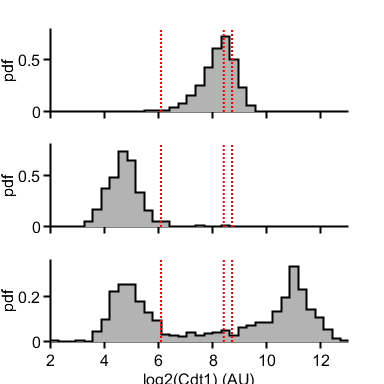

% set(gca,'FontSize',16)
ax = get(f,'children');
for i = 1:length(ax)
    axes(ax(i))
    xlim([2 13])
    vline(log2(gate.YFP1_S(2)))
        vline(endo_thresh)
        vline(endo_max)

    if i ~= 1
        set(gca,'xticklabel',{[]})
        %         set(gca,'xlabel','log2(Cdt1) (AU)')
    else
        
        xlabel('log2(Cdt1) (AU)')
        
    end
    
    
    
end

print_pdf([pwd() '\Figs\cdt1hist.pdf'])

**EdU comparison**

rng(1)
conds=[1 2];
poiAligned=3;
offset=0;

range = 4:.5:13;
timeGate = [0 .5];
midpoints = range + (range(2) -range(1))/2;
thresh = 2000;

f1 = figure;

gateVals = {{'FarRed1','YFP1'},{'FarRed1','YFP1'}};
rangeVals = {{[0 Inf],[0 Inf]},{[0 Inf],[2^10 2^1000]}};

ally = [];
group = [];
numb = 0;


for i=1:length(conds)
    ind=~isnan(S(conds(i)).POI(:,poiAligned))& ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i});
    
    tdata=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    gatedata=log2(S(conds(i)).YFP1(ind));
    ydata=(S(conds(i)).FarRed1(ind) - gate.FarRed1_G1(1)) ;
    wells = string(num2str(S(conds(i)).wellindex(ind,1:2)));
    
    %     if conds(i) == 4
    %         ydata = ydata + .75;
    %     end
    inds = tdata >= timeGate(1) & tdata <= timeGate(2);
    tdata = tdata(inds);
    ydata = ydata(inds);
    gatedata = gatedata(inds);
    wells = wells(inds);
    
    ally = [ally; ydata];
    group = [group; (numb+1)*ones(size(ydata))];
    numb = numb+1;
end
colors = [[0 113 188; 193 39 45]/255];
cols = repmat({colors(1,:),colors(2,:)}',1,1);
groupcol = [colors(1,:); colors(2,:)];

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'EdU (RFU)'])
% xticks([1 3 5 7 9]+.5)
xticklabels({'DMSO','DOX'})
% ylim([ 4 13])
axis square
% xtickangle(45)
% print_pdf([pwd() '\Figs\cdt1_jitter.pdf'])
meds = splitapply(@median,ally,group);
meds(1)/meds(2)

ans = 13.6630

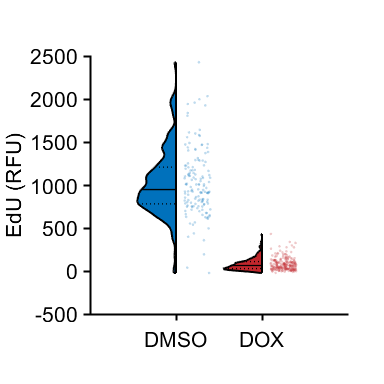

print_pdf([pwd() '\Figs\cdt1_jitter_linear.pdf'])

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

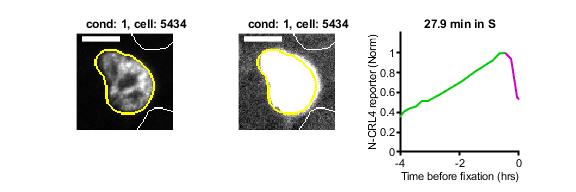

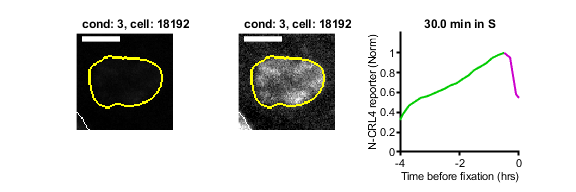

conds=[1 3];
poi_align = 4;
sizeBox = 40;
max_cells = 5;
rng(1)
range1 = [0 650];
range2 = [0 65];
pixel_size = .625/2; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[],[]};
include = {[5434],[18192],[]};
g1col = [0 .8 0];
scol = [.8 0 .8];
smooth_size = 5;
postbuff = 3;
filtPoints = floor((smooth_size - 1)/2);
endo_mid = 2.^endo_max;
for i = 1:length(conds)
    cond = conds(i);
    ind = S(cond).POI_time(:,poi_align) <= .5  & S(cond).POI_time(:,1) > 4;
    if ismember(cond,[2 3])
        ind = ind & S(cond).YFP1 < endo_mid*8 & S(cond).YFP1 > endo_mid*6;
    end
    ind = ind & S(cond).FarRed1 > prctile(S(cond).FarRed1(ind),45) & S(cond).FarRed1 < prctile(S(cond).FarRed1(ind),55) ; 
    cells = find(ind);
    
    cells = cells(~ismember(cells,exclude{i}));
    num_cells = min([max_cells length(cells)]);
    rsamp = randsample(length(cells),num_cells);
    cells = cells(rsamp);
        cells = include{i};
    for j = 1:length(cells)
        c = cells(j);
        crlNuc = S(cond).crlNormAct(c,:);
        offset = max(xTime) + (S(cond).POI_time(c,poi_align) - (numFrames - S(cond).POI(c,poi_align))/framesPerHr) ;
        grad = gradient(crlNuc);
        grad = grad(end);
        
        shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
        x = (S(cond).x(c))/1;
        y = (S(cond).y(c))/1;
        pois = S(cond).POI(c,:);
        
%         mkdir(fullfile(pwd(),'Images',shot,filesep))
%         copyfile([impath shot filesep shot '_mask.tif'],fullfile(pwd(),'Images',shot,filesep))
%         copyfile([impath shot filesep shot '_FarRed__round1.tif'],fullfile(pwd(),'Images',shot,filesep))
        im1=imread([impath shot filesep shot '_mask.tif']);
        im2=imread([impath shot filesep shot '_FarRed__round1.tif']);
        im1_fill = imfill(im1,'holes');
        im1_label = bwlabel(im1_fill);
        cell_label = im1_label(round(y),round(x));
        cell_mask = im1_label == cell_label;
        cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
        
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im1,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im1,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        cell_crop = imcrop(cell_bord,[xmin ymin width height]);
        
        figure('units','inches','Position',[0 0 3*2 2])
        subplot(1,3,1)
        hold on
        b = mat2gray(im2crop,range1);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
        set(gca,'FontSize',8)
        t=title(sprintf('cond: %d, cell: %d',cond,c),'FontSize',8);
        set(t,'interpreter','none');
        
        imwrite(b,[pwd() '\Figs\ind_S_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        subplot(1,3,2)
        hold on
        b = mat2gray(im2crop,range2);
        b = imoverlay(b,im1crop,'white');
        b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
        set(gca,'FontSize',8)
        t=title(sprintf('cond: %d, cell: %d',cond,c),'FontSize',8);
        set(t,'interpreter','none');
        
        subplot(1,3,3)
        ylim([0 1.2])
        hold on
        
        plot(xTime(1:pois(1)) - offset, crlNuc(1:pois(1)),'Color',[.5 .5 .5]);
        plot(xTime(pois(1):pois(poi_align)) - offset, crlNuc(pois(1):pois(poi_align)),'Color',g1col);
        plot([xTime(pois(poi_align):end) - offset 0], [crlNuc(pois(poi_align):end) crlNuc(end) + grad * (offset - max(xTime))],'Color',scol);

        set(gca,'FontSize',8)
        title(sprintf('%.1f min in S',S(cond).POI_time(c,poi_align)*60),'FontSize',8)
        xlabel('Time before fixation (hrs)','FontSize',8)
        ylabel('N-CRL4 reporter (Norm)','FontSize',8)
        ylim([0 1.2])
        xlim([-4 0])
        axis square
        print_pdf([pwd() '\Figs\S_images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
        
    end
    
end